# **Orbital Mechanics of a Human Cannon**

*Authors: *Drew Pang and Omar Salih

## Question:

From planet Earth, what angle and speed should a person be launched at to hit the moon? Is it even possible to launch a human out of a cannon to hit the moon? This is something that everyone has thought of at least once in their lives. This is a design question that will be optimized and tested in the form of a model, in order to answer our question. The unintuitive nature of orbital physics makes this question interesting to not only us, but astrophysicists, daredevils, and astronauts. Of course, we will have more assumptions to further narrow the scope of our model. We will learn about the intricacies of orbital mechanics, and how complex the process of launching things into orbit truly is. 

## **Model:**

Our question will be answered based on a graph displaying the launch trajectory of the human over the course of a month. It also displays the locations of the Earth and the Moon. The two parameters being altered are the launch angle and the launch velocity of the human. Below we have the schematic diagram and the FBDs associated with our model:

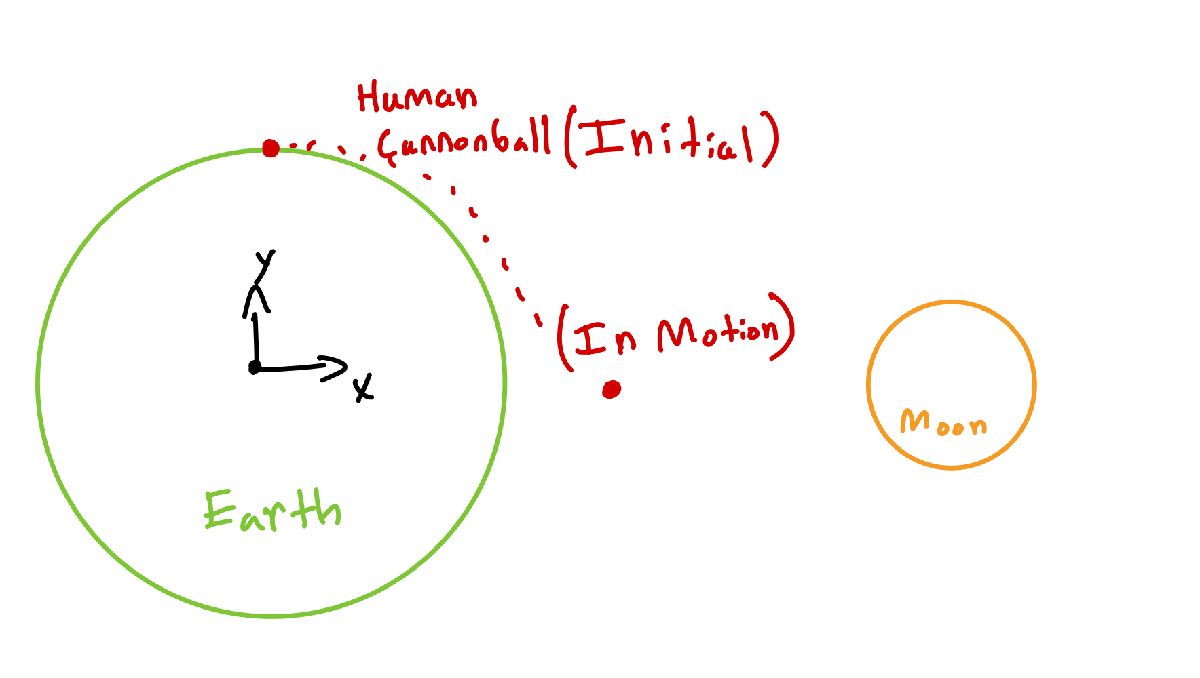

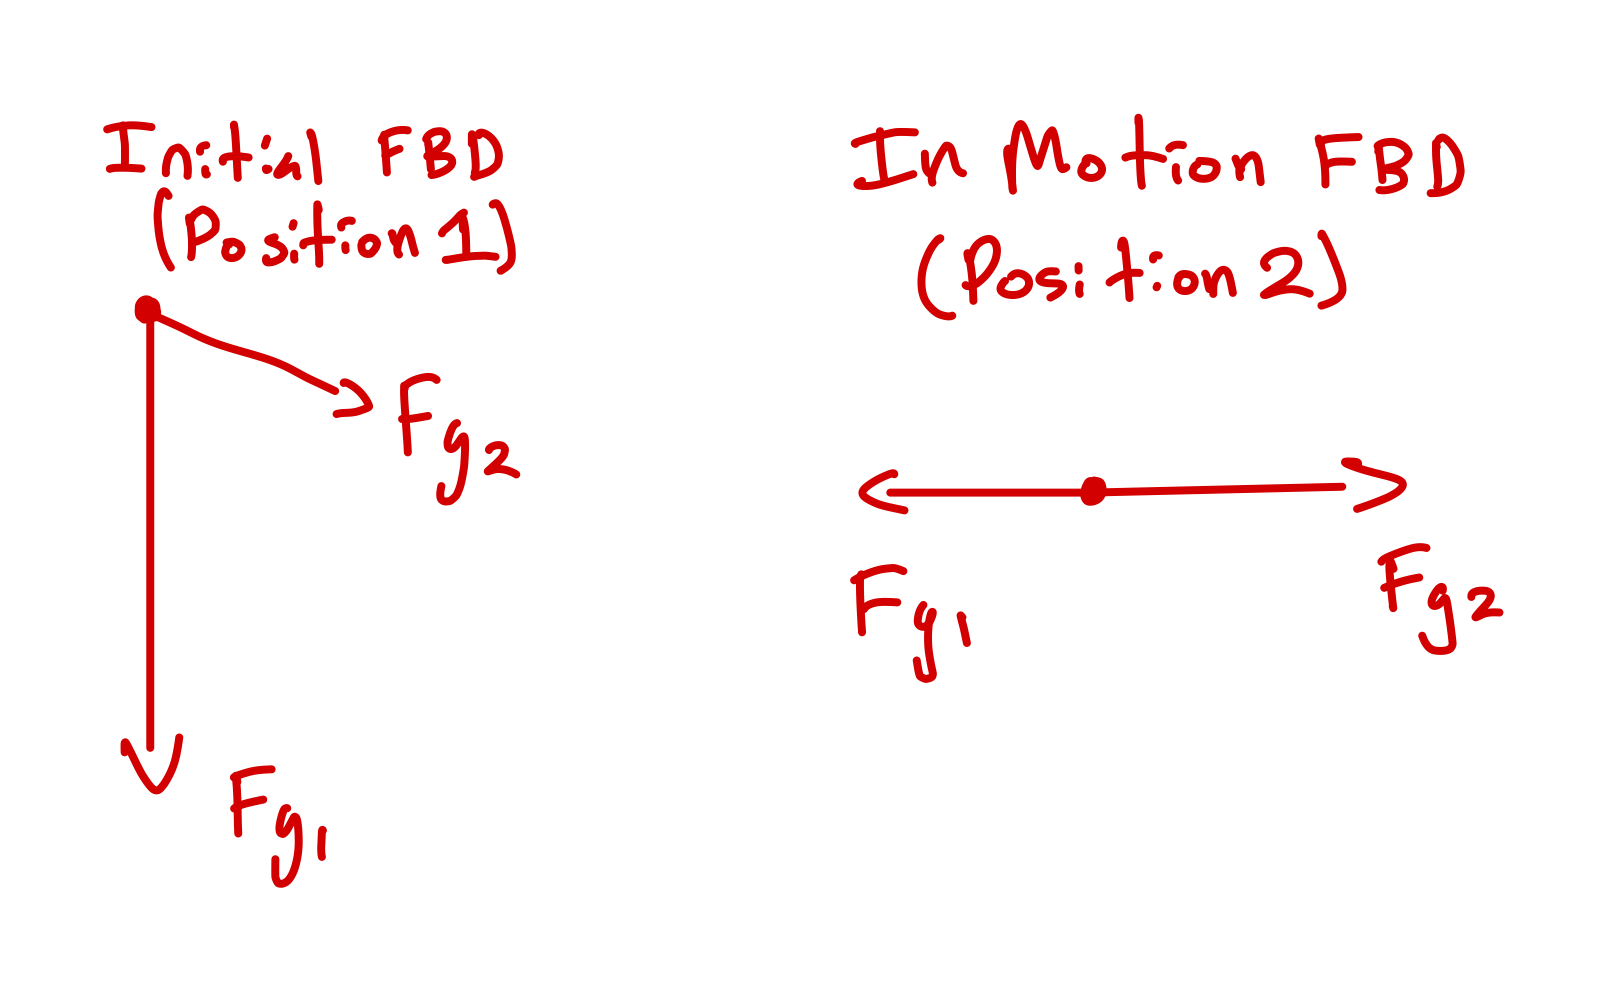

$F_{g1}$ = Force of gravity of the Earth

$F_{g2}$ = Force of gravity of the Moon

**Assumptions:**

What assumptions are you making? Are these good or bad assumptions?

For simplicities sake, the Earth and the Moon are stationary, since the model can get quite complex with an orbit. There’s also no air resistance within our model, because that would require us to have a ground launch and overcome the atmosphere. The Earth and Moon are perfect spheres to avoid collisions with irregular formations on the surfaces of these bodies. The human is a point-mass for the purpose of simplicity.

**Calculations**

Here is the mathematical representation of our model in the form of first and second-order ODEs:


$$\frac{d^2p}{dt^2} = \frac{Gm_1}{r_{1}^2}\hat{r_1}+\frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dv}{dt} = \frac{Gm_1}{r_{1}^2}\hat{r_1} + \frac{Gm_2}{r_{2}^2}\hat{r_2}\\
\frac{dp}{dt} = \hat{v}$$


$m_1$ = Mass of the Earth 

    % Should we include what the other values stand for?

$m_2$ = Mass of the Moon

$m_3
$ = Mass of the Human Cannonball

**Parameters**

The parameters in our model involve the launch angle and launch velocity of the human. In order to reach the moon, there has to be a specific launch velocity. For planet Earth, the escape velocity (disregarding atmospheric resistance) is about 11.2km/s, or 6.96 miles per second. This meant that we’d have to start our model launching the human at a speed of 11.2 km/s or faster. As for the launch angle, we’d be launching from an angle of 0° to 180°, because any angle outside this range would end up hitting the Earth’s surface. 

**Process**

Initially, our goal was to hit the moon directly, after several attempts testing various launch angles and velocities, we found it extremely difficult to hit the moon directly with multiple angles/velocities; there was only one set of angles and speeds that would hit the moon. We realized given the limitations of ode45 that the simulation wouldn’t stop when the moon was hit, because the timestep at that point was too long. We tried ode45, ode15s, ode89, and others, but still achieved the same result. Given this, we concluded that it would be more feasible of a model if we expanded the margin of error of our model. After doing that, we set up a parameter sweep from angles 1° to 80° and speeds from 10000 m/s to 16000 m/s.

## **Results:**

Before attempting to optimize our system, we need to create a model that accurately calculates the position of a body shot off of the Earth. We have created `body_2D_ode45() `to simulate our body in space.

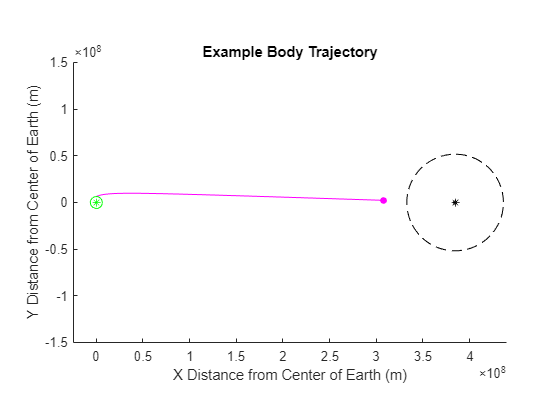

% Example body trajectory
launchAngle = 25;
launchVelocity = 12550;

[~, M] = body_2D_ode45(launchAngle, launchVelocity);

clf;
hold on
plot(M(:,1), M(:,2),'m');

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectory')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

Now that we have a working model, we can input some different values to simulate some different results. 

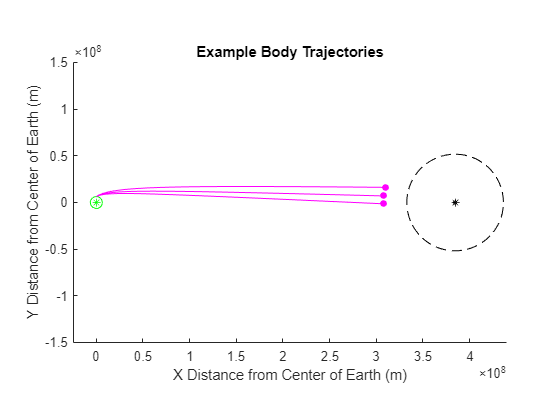

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 50000*1000;
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')

launchAngle = 25;
launchVelocity = 12470;
[~, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 30;
launchVelocity = 11900;
[~, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

launchAngle = 35;
launchVelocity = 11500;
[~, M] = body_2D_ode45(launchAngle, launchVelocity);
plot(M(:,1), M(:,2),'m');
plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)

xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

As you can see, our model stops the simulation when the body gets within 50,000km of the Moon. We can now used this to optimize our model.

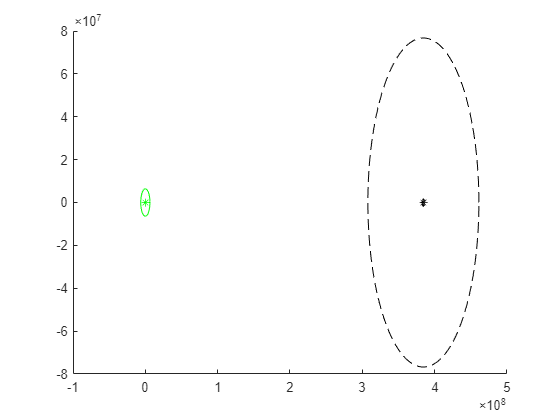

% Body trajectory examples
clf;
hold on

% Plot Earth
points = linspace(0, 2*pi, 500); r = 6.371e6;
x = r*cos(points); y = r*sin(points);
plot(x,y,'g'); plot(0,0,'*g')

% Plot Moon
r = 1.738e6; % Radius of the Moon
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'k'); plot(3.844e8,0, '*k')

% Plot lunar satelite orbit
r = 1.738e6 + 75000*1000; % Radius of the Margin of Error
x = r*cos(points) + 3.844e8; y = r*sin(points);
plot(x,y,'--k')


% Parameter Sweep

optimizedVelocity = []; % Is there any way to predefine this matrix to make the code run quicker?

for launchAngle = 0:1:80
    flag = 0;
    for launchVelocity = 10000:10:16000
        [T, M] = body_2D_ode45(launchAngle, launchVelocity);
        if T(end) ~= 60*60*24*7
            optimizedVelocity = [optimizedVelocity; launchVelocity];
            plot(M(:,1), M(:,2),'m');
            plot(M(end, 1), M(end, 2), "m.", "MarkerSize", 15)
            flag = 1;
        end
            if flag == 1
                break;
            end
    end 
end

Error using body_2D_ode45
Too many input arguments.


xlabel('X Distance from Center of Earth (m)'); ylabel('Y Distance from Center of Earth (m)');
title('Example Body Trajectories')
axis equal; xlim([-0.25*10^8 4.4*10^8]); ylim([-1.5*10^8 1.5*10^8]);

**Verification**

In order to verify our model, we wanted to map the forces of the Earth and the Moon over the course of time. What is generally expected is that the effect of the Earth's gravity decreases as it moves farther from the Earth, and the effect of the Moon's gravity increases as the projectile moves towards the Moon. 

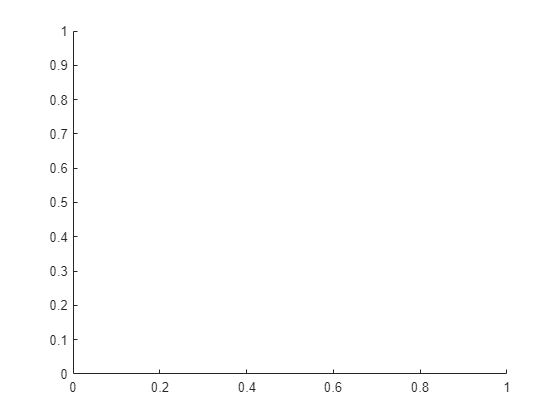

% Example body trajectory
launchAngle = 25;
launchVelocity = 12550;

[T, M] = body_2D_ode45(launchAngle, launchVelocity);

clf;
hold on

% Changing the velocities from x and y form to a single vector
Velocity = sqrt((M(:,3).^2) + (M(:,4).^2));
plot(T/8.64e3, M(:,5));

Index in position 2 exceeds array bounds. Index must not exceed 4.

## **Interpretation:** 

**Prompts:**

- How do the results answer the question?

- Do you think the answer is a good one? 

- What are the limitations of your model? 

- If you were going to continue developing your model, what next steps might you take? 

## Resources